% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
% Communication Systems
% Computer Assignment 1
% Fourier Transform, Correlation and Spectral Density
% Mohammad Mahdi Abdolhosseini
% Student Number: 810 198 434
% Fall 2021
% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
clc; clear; close all;

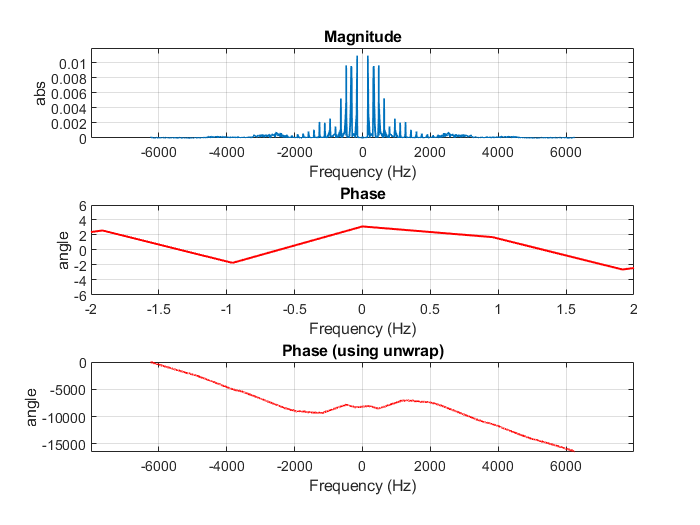

% Part 1

[data,Fs_data] = audioread('data.wav');  % Fs: Sampling frequency

f_data1 = fft(data);
f_data2 = fftshift(f_data1);
L_data = length(f_data2);             % Length of signal
abs_data = abs(f_data2/L_data);        % Magnitude
f = -Fs_data/2 : Fs_data/L_data : Fs_data/2 - Fs_data/L_data;

figure(1);
subplot(3,1,1);
plot(f, abs_data, 'linewidth', 1);
title('Magnitude');
xlabel('Frequency (Hz)');
ylabel('abs');
set(gca,'xtick', -6000 : 2000 : 6000, 'xlim', [-8000,8000]);
set(gca,'ytick', 0 : 0.002 : 0.01, 'ylim', [0,0.012]);
grid on;

phase_data1 = angle(f_data2);
subplot(3,1,2);
plot(f, phase_data1, 'r', 'linewidth', 1.2);
title('Phase');
xlabel('Frequency (Hz)');
ylabel('angle');
set(gca,'xtick', -2 : 0.5 : 2, 'xlim', [-2,2]);
set(gca,'ytick', -6 : 2 : 6, 'ylim', [-6,6]);
grid on;

phase_data2 = unwrap(phase_data1);
subplot(3,1,3);
plot(f, phase_data2, 'r', 'linewidth', 1.2);
title('Phase (using unwrap)');
xlabel('Frequency (Hz)');
ylabel('angle');
set(gca,'xtick', -6000 : 2000 : 6000, 'xlim', [-8000,8000]);
set(gca,'ytick', -15000 : 5000 : 0, 'ylim', [-16500,0]);
grid on;

% Part 2

[y,Fs_y] = audioread('y.wav');  % Fs: Sampling frequency
Fs_y

Fs_y = 44100

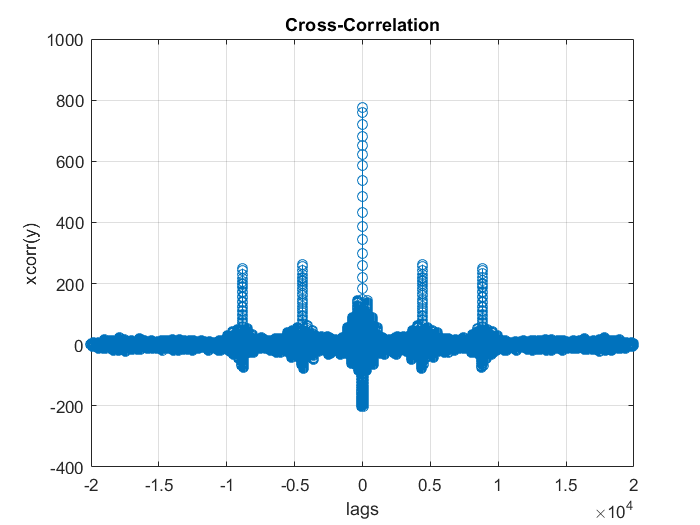

% Part 3

y1 = y(:,1);
[c,lags] = xcorr(y1);
figure(2);
stem(lags,c);
title('Cross-Correlation');
xlabel('lags');
ylabel('xcorr(y)');
set(gca,'xtick', -2*10^4 : 5000 : 2*10^4, 'xlim', [-2*10^4,2*10^4]);
set(gca,'ytick', -400 : 200 : 1000, 'ylim', [-400,1000]);
grid on;

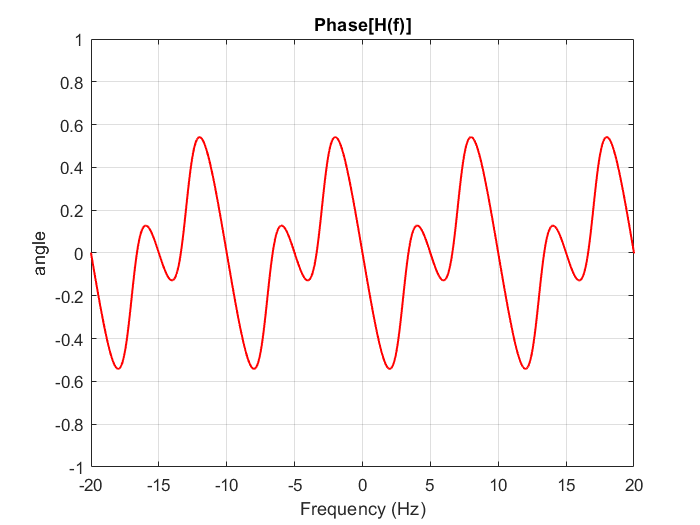

% Part 4

f_y1 = fft(y1);
L_y = length(f_y1);             % Length of signal
f2 = -Fs_y/2 : Fs_y/L_y : Fs_y/2 - Fs_y/L_y;
t = 1./f2;
Hf = 1 + 0.337*exp(-1i*2*pi*f2*0.1) + 0.320*exp(-1i*2*pi*f2*0.2);
plot(f2, angle(Hf), 'r', 'linewidth', 1.2);
title('Phase[H(f)]');
xlabel('Frequency (Hz)');
ylabel('angle');
set(gca,'xtick', -20 : 5 : 20, 'xlim', [-20,20]);
set(gca,'ytick', -1 : 0.2 : 1, 'ylim', [-1,1]);
grid on;

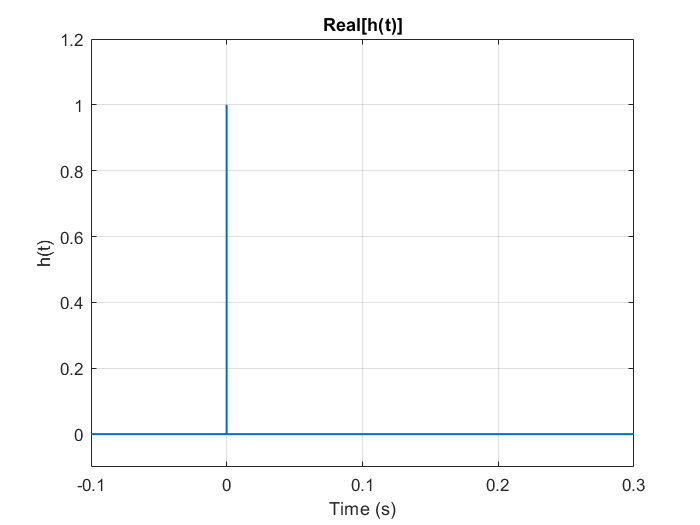

% Part 5

ht = ifft(Hf);
plot(t,real(ht), 'linewidth', 1.2);
title('Real[h(t)]');
xlabel('Time (s)');
ylabel('h(t)');
set(gca,'xtick', -0.1 : 0.1 : 0.5, 'xlim', [-0.1,0.3]);
set(gca,'ytick', -0.0 : 0.2 : 2, 'ylim', [-0.1,1.2]);
grid on;

% Part 6

x = filter(1,[1 zeros(1,4410-1) 0.337],y1);
x = filter(1,[1 zeros(1,8820-1) 0.320],x);
%plot(x);

% way2
% X2 = fftshift(f_y1) ./ transpose(Hf);
% x2 = ifft(X2);
% rx2 = real(x2);

% Part 7

sound(x,Fs_y);
audiowrite('x.wav',x,Fs_y);

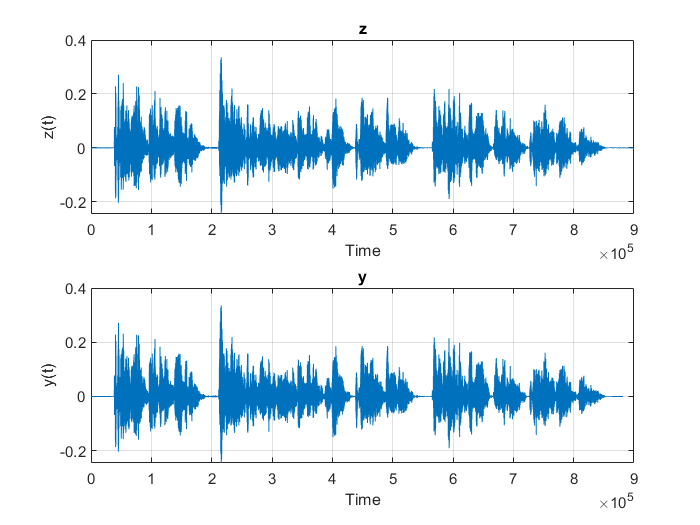

% Part 8

z = conv(x,real(ht));
subplot(2,1,1);
plot(z);
title('z');
xlabel('Time');
ylabel('z(t)');
set(gca,'xtick', 0 : 10^5 : 9*10^5, 'xlim', [0,9*10^5]);
grid on;
subplot(2,1,2);
plot(y1);
title('y');
xlabel('Time');
ylabel('y(t)');
grid on;

% Part 9

[mv,Fs_mv] = audioread('gettysburg10.wav'); % sorry it is not my voice :(
f_mv = fft(mv);
L_mv = length(f_mv);             % Length of signal
fmv = -Fs_mv/2 : Fs_mv/L_mv : Fs_mv/2 - Fs_mv/L_mv;
Hfm = 1 + 0.6*exp(-1i*2*pi*fmv*0.1) + 0.2*exp(-1i*2*pi*fmv*0.2);
htm = real(ifft(Hfm));
ymv = conv(mv,htm);
sound(ymv,Fs_mv);
audiowrite('my_voice.wav',ymv(1,1:L_mv),Fs_mv);

% Part 10

% Hf2 = 1 + 0.5*exp(-1i*2*pi*f2*0.2);
% Ryx = xcorr(y1,x);
% Rx = xcorr(x,x);
% plot(Ryx);
% hold on;
% f_Rx = fftshift(fft(Rx));
% Rx_Hf2 = f_Rx.*transpose(Hf2);
% Rx_conv_ht2 = ifft(Rx_Hf2);
% plot(Rx_conv_ht2);
% aError = immse(Ryx,Rx_conv_ht2)

% Ry = xcorr(y1);
% Gy = fft(Ry);
% Rx = xcorr(x);
% Gx = fft(Rx);
% aHfp2 = abs(Hf2).^2;
% bError = immse(Gy,Gx.*transpose(aHfp2))